Ganancia del estimador.

poles_e = [-0.65*p -0.6*p];
L = place(A',C',poles_e)';

Ganancias de realimentación de estados y del control integral.

A_ri = [A zeros(2,1); C 0];
B_ri = [B; 0];
poles_ri = [-0.3*p -0.35*p -0.4*p];
K_ri = place(A_ri,B_ri,poles_ri);
K_r = K_ri(1:2);
K_i = K_ri(3);

Condiciones inciales del sistema.

p0 = 2;
v0 = 1;
accDir = (-C*(A-B*K_r)^-1*B)^-1;

Posición de consigna.

targetPos = 5;

Se simula con la acción directa correcta.

open('controller.slx')

simOut = sim('controller.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
angVel = simOut.yout{2}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVel)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v$ (deg/s)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\accionDirecta.pdf')

Se simula el sistema para diferentes polos.

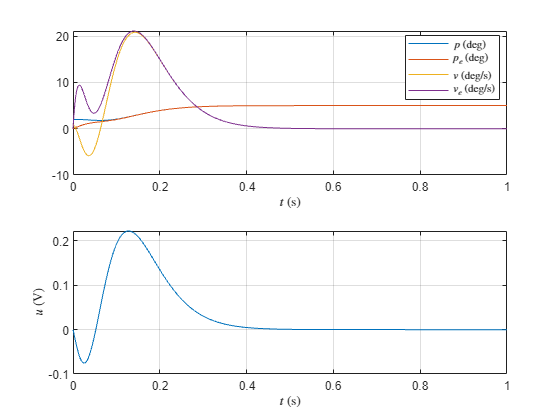

accDir = 0;
simOut = sim('controller.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
angVel = simOut.yout{2}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVel)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v$ (deg/s)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlJusto.pdf')

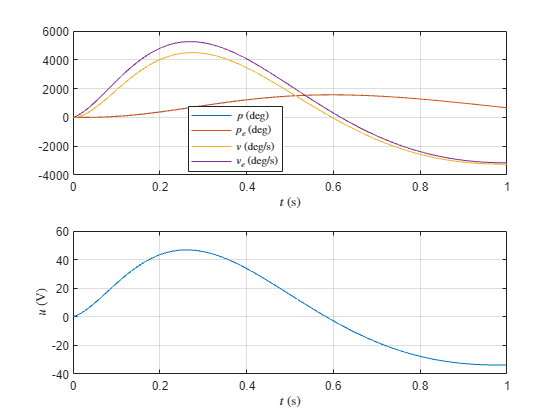

poles_e = [-0.065*p -0.06*p];
L = place(A',C',poles_e)';
poles_ri = [-0.03*p -0.035*p -0.04*p];
K_ri = place(A_ri,B_ri,poles_ri);
K_r = K_ri(1:2);
K_i = K_ri(3);

simOut = sim('controller.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
angVel = simOut.yout{2}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVel)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v$ (deg/s)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlLento.pdf')

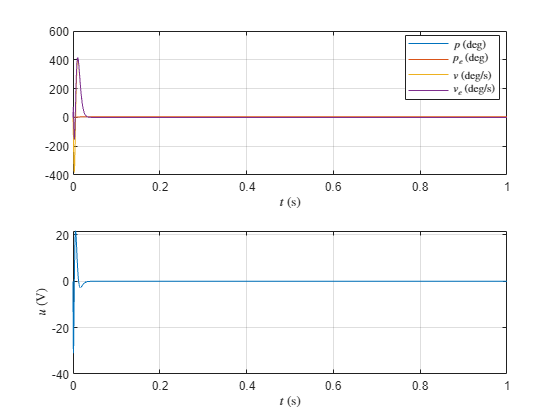

poles_e = [-6.5*p -6*p];
L = place(A',C',poles_e)';
poles_ri = [-3*p -3.5*p -4*p];
K_ri = place(A_ri,B_ri,poles_ri);
K_r = K_ri(1:2);
K_i = K_ri(3);

simOut = sim('controller.slx');
time = simOut.tout;
angPos = simOut.yout{1}.Values.Data;
angVel = simOut.yout{2}.Values.Data;
voltage = simOut.yout{3}.Values.Data;
angPosEst = simOut.yout{4}.Values.Data;
angVelEst = simOut.yout{5}.Values.Data;

figure
subplot(2,1,1)
plot(time,angPos)
hold on
plot(time,angPosEst)
plot(time,angVel)
plot(time,angVelEst)
grid on
legend('$p$ (deg)','$p_e$ (deg)','$v$ (deg/s)','$v_e$ (deg/s)', Location="best", Interpreter='latex')
xlabel('$t$ (s)', Interpreter='latex')
xlim([0 1])
subplot(2,1,2)
plot(time,voltage)
grid on
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$u$ (V)', Interpreter='latex')
xlim([0 1])
exportgraphics(gcf,'figuras\controlRapido.pdf')